# Tarjeta de audio

## Escaneamos dispositivos de audio

audioinfo=audiodevinfo

audioinfo = struct with fields:
     input: [1×2 struct]
    output: [1×2 struct]


## Crear objeto de audio

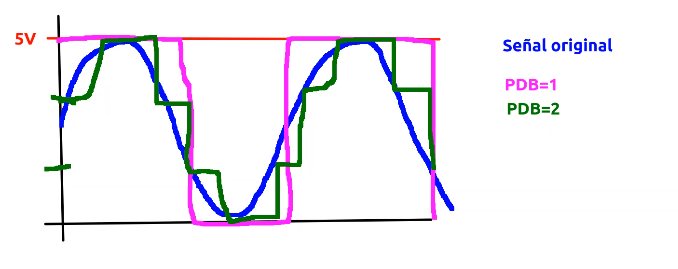Fig 1

Id=-1;

fs=8000; %Frecuancia de muestreo [Hz]. 
% A mayor fs mejor calidad pero mayor poder de procesamiento

CH_No=1; %No. canales de audio. Mono 1. Stereo 2.

BitDepth=8; %Profundidad de bits por muestra. 
% Pierdes menos información de las muestras mientras más grande es este número vease fig 1
%Es la resolución (o mínimo detectable) de un aparato.


%Default fs=8kHz BitDepth=8 1 CH
recordObject=audiorecorder(fs,BitDepth,CH_No,Id)

recordObject =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


%recordObject=audiorecorder es el default


## Grabación

T=2;
recordblocking(recordObject,T); 


## Ploteo

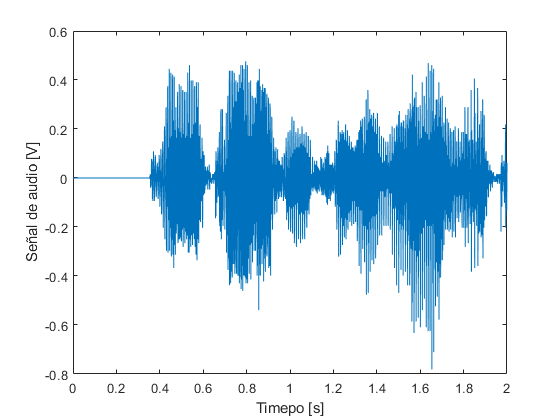

data_grabacion=getaudiodata(recordObject);%Guarda el auido como matriz

%Vector de timepo para el plot
t=1/fs : 1/fs : T;
plot(t,data_grabacion)
xlabel("Timepo [s]")
ylabel("Señal de audio [V]")

## Reproducción de audio

%play(recordObject); %Resprocude la grabación

sound(data_grabacion,fs)
%Puedes multiplicar cosas por fs y cambia el audio jejeje

## Espectro

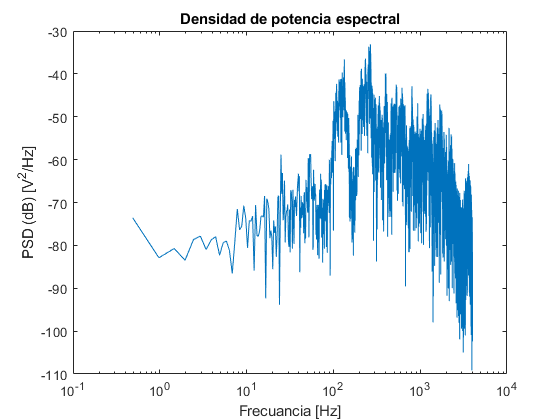

%Parametros importantes

N=numel(data_grabacion); %Num muestra de la señal
N_spec=N/50; %Numero de muestras espectrograma

% Funciones de descompocicion espectral
[Pxx_Per,F_Pxx]=periodogram(data_grabacion,rectwin(N),[],fs);
[~,F_Spec,T_Spec,Pxx_Spec]=spectrogram(data_grabacion,rectwin(N_spec),[],[],fs);

%Periodograma
figure
semilogx(F_Pxx,10*log10(Pxx_Per))
title("Densidad de potencia espectral")
xlabel("Frecuancia [Hz]")
ylabel("PSD (dB) [V^2/Hz]")


%Espectrograma
figure
p=pcolor(T_Spec,F_Spec,10*log10(Pxx_Spec));
set(p,'EdgeColor', 'none')
xlabel("Timepo [s]")
ylabel("Frecuencia [Hz]")
title("Espectrograma")
c=colorbar;
c.Label.String="PSD [V^2/Hz]"

c =   ColorBar (PSD [V^2/Hz]) with properties:

    Location: 'eastoutside'
      Limits: [-128.1810 -29.8152]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8167]
       Units: 'normalized'

  Show all properties


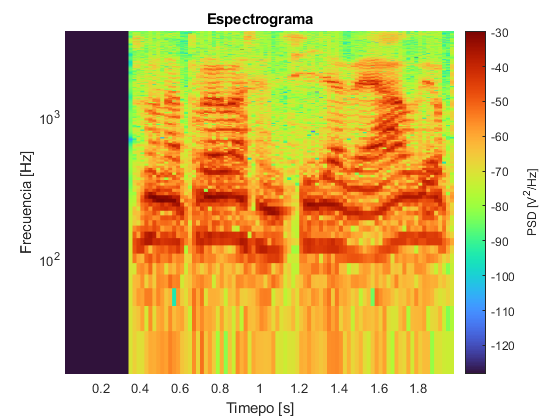

colormap('turbo')
set(gca,'YScale', 'log')

## Guardar audio

audiowrite("Output\voz.wav",data_grabacion,fs)


